##  Sans Bruit 

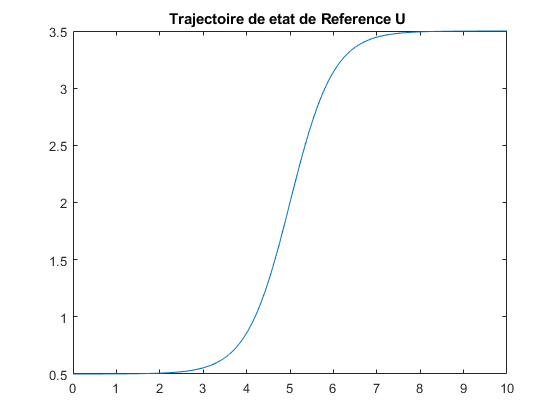


clear all;

% Parametres
epsilon = 1e-6;
G.lambda_1 = 500;
G.lambda_2 = 400;
G.lambda_3 = 10;

% Temps final
tfinal = 20;

% Conditions initiales
u0 = 1;  v0 = 2; r0 = 1.0;

tmp=linspace(0,10,100);
v_h = 5; v_l = 2; tmp_0 = 5;
u_ref = v_l + (v_h - v_l)*(1/2)* tanh(tmp - tmp_0);
v_ref = 2+v_l + (v_h - v_l)*(1/2)* tanh(tmp - tmp_0);
figure(5);plot(tmp,u_ref);title('Trajectoire de etat de Reference U ')

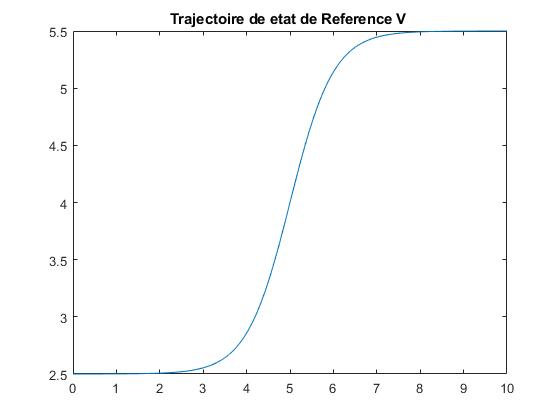

figure(6);plot(tmp,v_ref);title('Trajectoire de etat de Reference V ')


disp('Hovercraft simulation');

Hovercraft simulation


relTol = 1e-4;    absTol = 1e-7;    
options = odeset('RelTol', relTol, 'AbsTol', absTol);
%options=[];
[ts,Xs] = ode23tb(@(t,X) hovercraft(t,X,G,tmp,u_ref,v_ref,v_h,v_l), [0 tfinal], [u0 v0 r0],...
                                                                                  options);

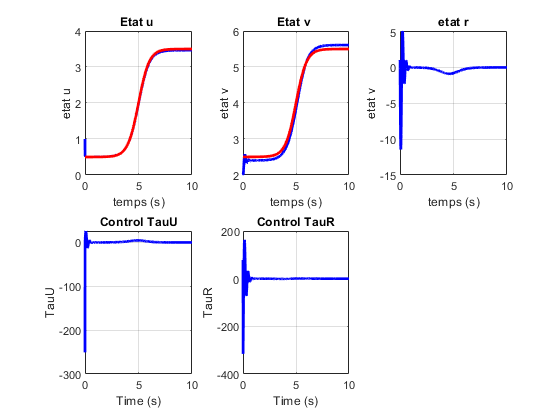

% extraction sources
u=Xs(:,1); v=Xs(:,2); r=Xs(:,3);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


figure(1);
% Position x
subplot(231); plot(ts, u, 'b', tmp, u_ref,'r', 'LineWidth', 2); grid; 
xlabel('temps (s)'); ylabel('etat u'); 
title('Etat u ','FontWeight','bold');
% Position y
subplot(232); plot(ts, v, 'b', tmp, v_ref,'r', 'LineWidth', 2); grid; 
xlabel('temps (s)'); ylabel('etat v');    
title('Etat v ','FontWeight','bold');

% Position v
subplot(233); plot(ts,r, 'b', 'LineWidth', 2); grid; 
xlabel('temps (s)'); ylabel('etat v'); 
title(' etat r ','FontWeight','bold');

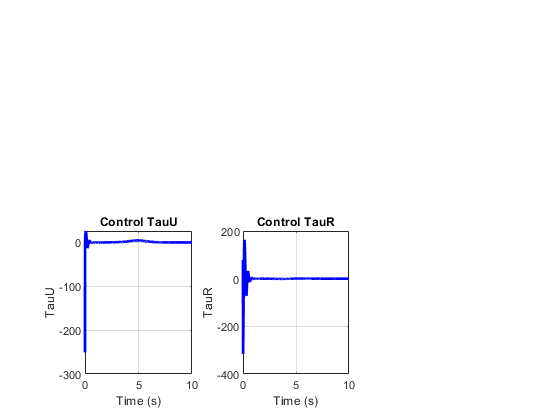


figure(10);
Bruit_u = 0.9*sin(5*u); 
plot(ts,Bruit_u);title('Les perturbations');xlabel('temps (s)'); ylabel('Bruit'); 

u_ref=interp1(tmp,u_ref,ts);
v_ref=interp1(tmp,v_ref,ts);

du_ref = (v_h-v_l)*(1/2).*(1-(u_ref).^2);
dv_ref = (v_h-v_l)*(1/2).*(1-(v_ref).^2);
ddv_ref = -2.*v_ref.*dv_ref;

% calcul des commandes
tau_u = du_ref - G.lambda_1.*(u - u_ref)- v.*r;
tau_r = -(1./(u + epsilon)).*( ddv_ref - G.lambda_2.*(v - v_ref) - G.lambda_3.*(- u.*r - dv_ref) + v.*(r.^2) + tau_u.*r);
  
% commandes tau_u
subplot(234); plot(ts, tau_u,'b', 'LineWidth', 2); grid; 
xlabel('Time (s)'); ylabel('TauU');
title('Control TauU');

% commandes tau_r
subplot(235); plot(ts, tau_r,'b', 'LineWidth', 2); grid; 
xlabel('Time (s)'); ylabel('TauR');
title('Control TauR');

## avec Bruit 


clear all;

% Parametres
epsilon = 1e-6;
G.lambda_1 = 500;
G.lambda_2 = 400;
G.lambda_3 = 10;

% Temps final
tfinal = 20;

% Conditions initiales
u0 = 1;  v0 = 2; r0 = 1.0;

tmp=linspace(0,10,100);
v_h = 5; v_l = 2; tmp_0 = 5;
u_ref = v_l + (v_h - v_l)*(1/2)* tanh(tmp - tmp_0);
v_ref = 2+v_l + (v_h - v_l)*(1/2)* tanh(tmp - tmp_0);
% figure(5);plot(tmp,u_ref)
% figure(6);plot(tmp,v_ref)

disp('Hovercraft simulation');

Hovercraft simulation


relTol = 1e-4;    absTol = 1e-7;    
options = odeset('RelTol', relTol, 'AbsTol', absTol);
%options=[];
[ts,Xs] = ode23tb(@(t,X) hovercraftBruit(t,X,G,tmp,u_ref,v_ref,v_h,v_l), [0 tfinal], [u0 v0 r0],...
                                                                                  options);

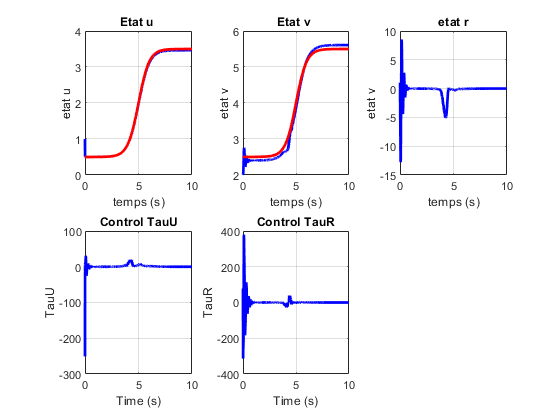

% extraction sources
u=Xs(:,1); v=Xs(:,2); r=Xs(:,3);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


figure(2);
% Position x
subplot(231); plot(ts, u, 'b', tmp, u_ref,'r', 'LineWidth', 2); grid; 
xlabel('temps (s)'); ylabel('etat u'); 
title('Etat u ','FontWeight','bold');
% Position y
subplot(232); plot(ts, v, 'b', tmp, v_ref,'r', 'LineWidth', 2); grid; 
xlabel('temps (s)'); ylabel('etat v');    
title('Etat v ','FontWeight','bold');

% Position v
subplot(233); plot(ts,r, 'b', 'LineWidth', 2); grid; 
xlabel('temps (s)'); ylabel('etat v'); 
title(' etat r ','FontWeight','bold');


u_ref=interp1(tmp,u_ref,ts);
v_ref=interp1(tmp,v_ref,ts);

du_ref = (v_h-v_l)*(1/2).*(1-(u_ref).^2);
dv_ref = (v_h-v_l)*(1/2).*(1-(v_ref).^2);
ddv_ref = -2.*v_ref.*dv_ref;

% calcul des commandes
tau_u = du_ref - G.lambda_1.*(u - u_ref)- v.*r;
tau_r = -(1./(u + epsilon)).*( ddv_ref - G.lambda_2.*(v - v_ref) - G.lambda_3.*(- u.*r - dv_ref) + v.*(r.^2) + tau_u.*r);
  
% commandes tau_u
subplot(234); plot(ts, tau_u,'b', 'LineWidth', 2); grid; 
xlabel('Time (s)'); ylabel('TauU');
title('Control TauU');

% commandes tau_r
subplot(235); plot(ts, tau_r,'b', 'LineWidth', 2); grid; 
xlabel('Time (s)'); ylabel('TauR');
title('Control TauR');

function [dotX]= hovercraft(t, X , G, tmp, u_ref, v_ref,v_h,v_l)
%global i

%current stat
u=X(1,:); v=X(2,:); r=X(3,:);

epsilon = 1e-6;

%control computation
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
u_ref=interp1(tmp,u_ref,t);
v_ref=interp1(tmp,v_ref,t);

du_ref = (v_h-v_l)*(1/2)*(1-(u_ref)^2);
dv_ref = (v_h-v_l)*(1/2)*(1-(v_ref)^2);
ddv_ref = -2*v_ref*dv_ref;

% calcul des commandes
tau_u = du_ref - G.lambda_1.*(u - u_ref)- v.*r;
tau_r = -(1./(u + epsilon)).*( ddv_ref - G.lambda_2.*(v - v_ref) - G.lambda_3.*(- u.*r - dv_ref) + v.*(r.^2) + tau_u.*r);

% equations du systeme

dotu = v.*r + tau_u;
dotv = -u.*r;
dotr = tau_r;

% renvoi d'arguments 
dotX = [dotu dotv dotr]';
  
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end

function [dotX] = hovercraftBruit(t, X , G, tmp, u_ref, v_ref,v_h,v_l)
%global i

%current stat
u=X(1,:); v=X(2,:); r=X(3,:);
epsilon = 1e-6;

Bruit_u = 0.9*sin(5*u); 
Bruit_v = 0.9*sin(5*v); 
Bruit_r = 0.9*sin(5*r);

% Bruit_u = 0 ; 
% Bruit_v = 0 ; 
% Bruit_r = 0;

%control computation
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
u_ref=interp1(tmp,u_ref,t);
v_ref=interp1(tmp,v_ref,t);

du_ref = (v_h-v_l)*(1/2)*(1-(u_ref)^2);
dv_ref = (v_h-v_l)*(1/2)*(1-(v_ref)^2);
ddv_ref = -2*v_ref*dv_ref;

% % calcul des commandes
% tau_u = du_ref - G.lambda_1.*((u + Bruit_u) - u_ref)- (v + Bruit_v).*(r + Bruit_r);
% tau_r = -(1./((u + Bruit_u) + epsilon)).*( ddv_ref - G.lambda_2.*((v + Bruit_v) - v_ref) - G.lambda_3.*(-(u + Bruit_u).*(r + Bruit_r) - dv_ref) + (v + Bruit_v).*((r + Bruit_r).^2) + tau_u.*(r + Bruit_r));

% calcul des commandes
tau_u = du_ref - G.lambda_1.*(u - u_ref)- v.*r;
tau_r = -(1./(u + epsilon)).*( ddv_ref - G.lambda_2.*(v - v_ref) - G.lambda_3.*(- u.*r - dv_ref) + v.*(r.^2) + tau_u.*r);

% equations du systeme

dotu = (v + Bruit_v).*(r + Bruit_r) + tau_u;
dotv = -(u + Bruit_u).*(r + Bruit_r);
dotr = tau_r;

% renvoi d'arguments 
dotX = [dotu dotv dotr]';
  
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end